# Example 1: executing a simulation 

### This assumes the database and default data has been set up

## 1. add directory contents to exec path

% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), '\');
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), '\')

root_directory = 'G:\Dropbox\NASA\uavtestbed'

% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load the api
api = jsondecode(fileread('sql/api.json'));

## 2. Retrieve UAV and preface info from db

- flight num / flight id

- last timestamp

- stop codes and group ids

% the database connection
conn = db_connect('nasadb');

% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS)

uav_tb = 2×15 table
    serial_number       common_name       id    airframe_id    battery_id    m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    max_flight_time    dynamics_srate
    _____________    _________________    __    ___________    __________    _____    _____    _____    _____    _____    _____    _____    _____    _______________    ______________

     {'DF1BFD'}      {'default'      }    11         1              2         10        9        8     

% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the tarot)

uav = load_uav(conn, uav_tb.serial_number{2}, api);

% uav = load('params/uav.mat').uav;
uav

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 15
                 id: 22
     dynamics_srate: 0.0250
               mass: 10.6600


### Load the stop_code_tb and group_tb

% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;")

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb")

group_id_tb = 1×2 table
    id        info    
    __    ____________

    1     {'examaple'}


group_id = group_id_tb.id(1);

### Look at the flight summary table and get the last timestamp and flight_id

- since these are simulations, the simulation time will grow beyond real time so we cannot just use " datestr(now) " as the start time

- The start time is important because the telemetry data is indexed via timestamp

- the start and stop timestamps in the flight_summary_tb are used to access the flight telemetry data for that flight

- the flight_id refers to the id field of flight_summary_tb

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from flight_summary_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second')

dt_start = datetime
   27-Aug-2021 14:16:28


% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from flight_summary_tb order by id desc limit 1;')) + 1


flight_id =

  0×1 empty double column vector



if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from flight_summary_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

% close the connection and clear the table (the data is in the uav struct now)
conn.close();
clear('uav_tb', 'conn');


## 3. Load the trajectory

% load the trajectory information
% there are 37 different trajectories, this function will return one that
% is closest to the second parameter in the function (uav.max_flight_time)
% with valid numbers (minutes) between 6 and 22. 
%trajectory = get_trajectory('trajectories/trajectories.csv', uav.max_flight_time, desired_velocity);
trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < uav.max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')
trajectory = get_trajectory(trajectory_tb, 1)

trajectory_tb = 8×13 table
    id    path_distance    path_time    risk_factor         start            destination             x_waypoints               y_waypoints                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           

### Plot the trajectory

f2 = figure(2); clf;

trajectory = struct with fields:
               id: 7
    path_distance: 656.5600
        path_time: 8.4200
      risk_factor: 0.0100
            start: [50 25]
      destination: [350 350]
     x_ref_points: [505×2 double]
     y_ref_points: [505×2 double]
      sample_time: 1
           reward: 1
              map: 'map1'
        waypoints: [2×2 double]
             path: [26×2 double]


map = load(sprintf('trajectories/%s.mat', trajectory.map)).(sprintf('%s', trajectory.map));
hold on;
show(map);
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path-1)
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")
clear map;

## 4. Setup simulation params

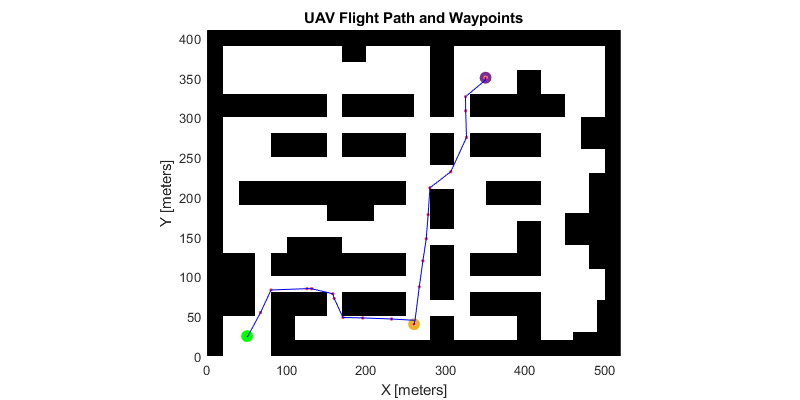

% stop measure on the simulation, in general it should stop before this

sim_params.max_sim_time = 4000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 10; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .2; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.075; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after
sim_params.perf_param_thresh.avg_pos_err  = 2.8; % this is checked after
sim_params.perf_param_thresh.pos_err_var  = 10; % check this 

% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/IC_HoverAt10fttarot.mat').IC;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;
if uav.battery.v0 < 4.3
    sim_params.battery_estimator.soc_ocv = interp1([sim_params.battery_estimator.soc_ocv(1) sim_params.battery_estimator.soc_ocv(end)], [3.04 4.2], sim_params.battery_estimator.soc_ocv);
end

if strcmp(uav.uav.common_name, 'default')
    sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
    sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;
end

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

## 5. Load process data

- environment (wind)

- degradation (battery, motors)

### a. this will get a single process (better to use method b)

%     conn = db_connect('nasadb');
%     process_type = 'degradation';
%     subtype1 = 'battery';
%     subtype2 = 'capacitance';
%     description = 'continuous';
%     %% returns all process data
%     process_tb = select(conn, eval(api.matlab.process.LOAD_PROCESS))
%     %% use .parameters{1} to get only the degradation parameters
%     params = select(conn, eval(api.matlab.process.LOAD_PROCESS)).parameters{1}
%     res = jsondecode(params);
%     uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
%     
%     subtype2 = 'resistance';
%     params = select(conn, eval(api.matlab.process.LOAD_PROCESS)).parameters{1}
%     res = jsondecode(params);

process_tb = 1×9 table
    id         type           subtype1         subtype2        id_1    type_id           description                       source                                                  parameters                                   
    __    _______________    ___________    _______________    ____    _______    __________________________    _____________________________    _______________________________________________________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'}     5         1       {'continuous usage based'}    {'NASA prognostics data set'}    {'{"q_coef": [-4.89511264247582e-08, 2.57136010019803e-05, 21.7779510188925

%     uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
%     conn.close();

params = '{"q_coef": [-4.89511264247582e-08, 2.57136010019803e-05, 21.7779510188925]}'

### b. this will get all processes of a given type (degradation or environment)

conn = db_connect('nasadb');
process_type = 'degradation';
description = 'continuous';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
process_tb = process_tb(contains(string(process_tb.description), description),:)

params = '{"r_coef": [-6.45448007483688e-30, 1.28205128205128e-09, -6.00406078520637e-21, 0.00110000000000001]}'

proc_tb = process_tb(contains(string(process_tb.subtype1), 'battery'), :)
for i = 1:height(proc_tb)
    params = proc_tb(i, 'parameters').parameters{1}
    res = jsondecode(params);
    uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
proc_tb =  process_tb(contains(string(process_tb.subtype1), 'motor'), :)
for i = 1:height(proc_tb)
    params = proc_tb(i, 'parameters').parameters{1}
    res = jsondecode(params);

process_tb = 10×9 table
    id         type           subtype1             subtype2            id_1    type_id             description                        source                                                               parameters                                                
    __    _______________    ___________    _______________________    ____    _______    _____________________________    _____________________________    _________________________________________________________________________________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'        }      5        1       {'continuous usage based'   }    {'NASA prognostics dat

    uav.motors(i).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';

proc_tb = 2×9 table
    id         type           subtype1             subtype2            id_1    type_id           description                       source                                                               parameters                                                
    __    _______________    ___________    _______________________    ____    _______    __________________________    _____________________________    _________________________________________________________________________________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'        }     5         1       {'continuous usage based'}    {'NASA prognostics data set'}    {'

end
process_type = 'environment';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  
for i = 1:height(process_tb)
    params = process_tb(i, 'parameters').parameters{1}

params = '{"q_coef": [-4.89511264247582e-08, 2.57136010019803e-05, 21.7779510188925]}'

params = '{"r_coef": [-6.45448007483688e-30, 1.28205128205128e-09, -6.00406078520637e-21, 0.00110000000000001]}'

    res = jsondecode(params);

proc_tb = 8×9 table
    id         type          subtype1            subtype2            id_1    type_id             description                   source                                            parameters                                  
    __    _______________    _________    _______________________    ____    _______    _____________________________    ___________________    _____________________________________________________________________________

    3     {'degradation'}    {'motor'}    {'internal resistance'}      7        3       {'continuous usage based v1'}    {'experimentation'}    {'{"r_coef": [9.50624857260528e-10,7.36450668948172e-06,0.263497796082376]}'}
    3  

    fn = fieldnames(res);
    for j = 1:length(fn)
        processes.(sprintf("%s", process_type)).(sprintf("%s", process_tb(i, 'subtype1').subtype1{1})).(sprintf("%s", process_tb(i, 'subtype2').subtype2{1})).(sprintf("%s", fn{j})) = res.(fn{j})
    end
end

params = '{"r_coef": [9.50624857260528e-10,7.36450668948172e-06,0.263497796082376]}'

params = '{"r_coef": [8.06755398661245e-10,6.52894024631680e-06,0.262289662927966]}'

params = '{"r_coef": [9.29515615816656e-11,8.94737997218633e-06,0.268694863884113]}'

params = '{"r_coef": [1.70509987509355e-10,9.81058750961606e-06,0.265337769108691]}'

params = '{"r_coef": [2.82792767894577e-10,1.53025640617371e-05,0.266051480761262]}'

params = '{"r_coef": [2.54237790214439e-10,9.40419648401406e-06,0.265391730156094]}'

params = '{"r_coef": [4.17473351928237e-10,1.47027567469104e-05,0.261595719415796]}'

params = '{"r_coef": [3.97802703577498e-10,1.62865097051639e-05,0.262471936739113]}'

conn.close()
clear('conn', 'description', 'i', 'j', 'params', 'proc_tb', 'process_tb', 'process_type', 'res');

process_tb = 1×9 table
    id         type          subtype1    subtype2    id_1    type_id                                    description                                                  source                                        parameters                       
    __    _______________    ________    ________    ____    _______    ____________________________________________________________________________    ________________________________    ________________________________________________________

    4     {'environment'}    {'wind'}    {'gust'}     4         4       {'simulated wind gusts through direct application of force to the airframe'}    {'generated by experimentati

## 5. Simulate

tic
if strcmp(uav.uav.common_name, 'tarot t18 uav')
    sim('simulink/uav_simulation_tarot.slx');
else 
    sim('simulink/uav_simulation.slx');
end
toc

params = '{"x": [1.0, 0.25], "y": [0.5, 0.5], "z": [0.1, 0.1]}'

processes = struct with fields:
    environment: [1×1 struct]


processes = struct with fields:
    environment: [1×1 struct]


processes = struct with fields:
    environment: [1×1 struct]


#### calculate dt_stop

dt_stop = dt_start + minutes(time.Data(end, 1))

## 5a. check stop codes and system performance parameter thresholds

- stop codes 1-4 are checked in simulation

stop_code_tb
stop_code = max(find(any(stop_codes.Data(:,:))))
string(stop_code_tb.description(stop_code_tb.id==stop_code))

#### check the average position error threshold

if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'))
end

#### check the minimum state of health for the battery threshold (battery.Q aka q_deg)

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt

Elapsed time is 59.213717 seconds.


    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'))
end

dt_stop = datetime
   27-Aug-2021 14:24:53


## 6. Update component degradation parameters

- battery

if strcmp(string(uav.uav.common_name), "tarot t18 uav")

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


    avg_current = abs(mean(battery.battery_true.i.Data(:)))

stop_code = 4

    flight_time = time.Data(end)/60 % time.Data is already in minutes, time.time however is in seconds

ans = "arrival success"

    amp_hours = avg_current * flight_time;
    uav.battery.amp_hours = uav.battery.amp_hours + amp_hours;
    uav.battery.amp_hours
    uav.battery.age = uav.battery.amp_hours / uav.battery.lifetime_amp_hrs;
    uav.battery.age
    uav.battery.Q = polyval(uav.battery.q_coef, uav.battery.amp_hours);
    uav.battery.Q
    uav.battery.R0 = polyval(uav.battery.r_coef, uav.battery.amp_hours);
    uav.battery.R0

- motors

    for i = 1:length(uav.motors)
        uav.motors(i).age = uav.motors(i).age + motors.(sprintf('m%d',i)).current.Data(end)*flight_time;
        uav.motors(i).Req = polyval(uav.motors(i).r_coef, uav.motors(i).age);
    end
    clear('avg_current', 'flight_time', 'amp_hours');
end

avg_current = 64.5328

flight_time = 0.2731

ans = 17.6242

ans = 0.0013

ans = 21.7784

ans = 0.0011

## 6a. charge the battery

persist the battery state

uav.battery.v = res.battery_state_params.v.Data(end);
uav.battery.z = res.battery_state_params.z.Data(end);

standard charging practice is 1C

u = -uav.battery.Q;

var_names = 1×30 string array
    "id"    "stop_code"    "z_start"    "z_end"    "v_start"    "v_end"    "m1_avg_current"    "m2_avg_current"    "m3_avg_current"    "m4_avg_current"    "m5_avg_current"    "m6_avg_current"    "m7_avg_current"    "m8_avg_current"    "avg_pos_err"    "max_pos_err"    "std_pos_err"    "avg_ctrl_err"    "max_ctrl_err"    "std_ctrl_err"    "distance"    "flight_time"    "avg_current"    "amp_hours"    "dt_start"    "dt_stop"    "trajectory_id"    "uav_id"    "flight_num"    "group_id"


sim('continuous_battery.slx')
uav.battery.v = res.battery_state_params.v.Data(end);
uav.battery.z = res.battery_state_params.z.Data(end);
avg_current = abs(mean(res.u.Data));
time = res.time.Data(end)/3600;
amp_hours = avg_current * time;
uav.battery.amp_hours = uav.battery.amp_hours + amp_hours;
uav.battery.age = uav.battery.amp_hours / uav.battery.lifetime_amp_hrs;

flight_summary_tb = 1×29 table
    stop_code    z_start     z_end     v_start    v_end     m1_avg_current    m2_avg_current    m3_avg_current    m4_avg_current    m5_avg_current    m6_avg_current    m7_avg_current    m8_avg_current    avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours          dt_start                dt_stop           trajectory_id    uav_id    flight_num    group_id
    _________

### Update degradation parameters

uav.battery.Q = polyval(uav.battery.q_coef, uav.battery.amp_hours);
uav.battery.R0 = polyval(uav.battery.r_coef, uav.battery.amp_hours);

## 7. Update the asset age in the database

## 8. Insert summary data into the db

% the database connection
conn = db_connect('nasadb');

% get the variable names, but note "id" isn't used
var_names = get_column_names(conn, 'flight_summary_tb')
flight_summary_tb = table(max(find(any(stop_codes.Data(:,:)))), ...
                          battery.battery_true.z.Data(1), ...
                          battery.battery_true.z.Data(end), ...
                          battery.battery_true.v.Data(1), ...
                          battery.battery_true.v.Data(end), ...
                          mean(motors.m1.current), ...
                          mean(motors.m2.current), ...
                          mean(motors.m3.current), ...
                          mean(motors.m4.current), ...
                          mean(motors.m5.current), ...
                          mean(motors.m6.current), ...
                          mean(motors.m7.current), ...
                          mean(motors.m8.current), ...
                          mean(errors.euclidean_pos_err), ...
                          max(errors.euclidean_pos_err), ...
                          std(errors.euclidean_pos_err), ...
                          mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4), ...
                          time.Time(end)/60, ...
                          mean(battery.battery_true.i.Data), ...
                          mean(battery.battery_true.i.Data)*time.Time(end)/60/60, ...
                          dt_start, ...
                          dt_start + minutes(time.Time(end)/60), ...
                          trajectory.id, ...
                          uav.id, ...
                          flight_num, ...
                          group_id, ...
                          'VariableNames',  cellstr(var_names(1,2:end)))
% write the data to the database
sqlwrite(conn, 'flight_summary_tb', flight_summary_tb);
conn.commit();
conn.close();
clear conn;

## 9. Get the degradation data and insert it

% the database connection
conn = db_connect('nasadb');

% get var names
var_names = get_column_names(conn, 'flight_degradation_tb')

#### flight_id refers to the id field of the flight_summary_tb. This is pulled from the beginning

#### also, on this flight we are only inserting 4 parameters, the 4 required parameters to use this table

var_names = {'flight_id' 'q_deg' 'r_deg' 'm_deg'}
flight_degradation_tb = table(flight_id, ...
                              uav.battery.Q, ...
                              uav.battery.R0, ...
                              uav.motors(2).Req, ...
                              'VariableNames', var_names)
clear('var_names');
% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_degradation_tb', flight_degradation_tb);
conn.commit();
conn.close();
clear conn;

## 10. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;
1/mean(diff(t_dynamics))

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;
1/mean(diff(t_sim))
clear('t_batt', 't_dynamics', 't_sim');

### Battery data

sample_rate = 1;

battery_tt = sync_telemetry_data(battery, sample_rate, time.Time(:))

### Errors data

errors_tt = sync_telemetry_data(errors, sample_rate, time.Time(:));
errors_tt.Properties.VariableNames{'pos_err_x_pos_err'} = 'x_pos_err';
errors_tt.Properties.VariableNames{'pos_err_y_pos_err'} = 'y_pos_err';
errors_tt.Properties.VariableNames{'ctrl_err_x_error'}  = 'x_ctrl_err';
errors_tt.Properties.VariableNames{'ctrl_err_y_error'}  = 'y_ctrl_err';
errors_tt

### Environment data

environment_tt = sync_telemetry_data(environment, sample_rate, time.Time(:));
environment_tt.Properties.VariableNames{'wind_gust-1'}  = 'wind_gust_x';
environment_tt.Properties.VariableNames{'wind_gust-2'}  = 'wind_gust_y';
environment_tt.Properties.VariableNames{'wind_gust-3'}  = 'wind_gust_z';
environment_tt

### Motor data

motors_tt = sync_telemetry_data(motors, sample_rate, time.Time(:))

### Position data

position_tt = sync_telemetry_data(position, sample_rate, time.Time(:));
position_tt.Properties.VariableNames{'gps-1'}  = 'x_pos_gps';
position_tt.Properties.VariableNames{'gps-2'}  = 'y_pos_gps';
position_tt.Properties.VariableNames{'gps-3'}  = 'z_pos_gps';
position_tt.Properties.VariableNames{'true-1'}  = 'x_pos_true';
position_tt.Properties.VariableNames{'true-2'}  = 'y_pos_true';
position_tt.Properties.VariableNames{'true-3'}  = 'z_pos_true';
position_tt

### Velocity data

velocity_tt = sync_telemetry_data(velocity, sample_rate, time.Time(:));
velocity_tt.Properties.VariableNames{'gps-1'}  = 'x_vel_gps';
velocity_tt.Properties.VariableNames{'gps-2'}  = 'y_vel_gps';
velocity_tt.Properties.VariableNames{'gps-3'}  = 'z_vel_gps';
velocity_tt.Properties.VariableNames{'true-1'}  = 'x_vel_true';
velocity_tt.Properties.VariableNames{'true-2'}  = 'y_vel_true';
velocity_tt.Properties.VariableNames{'true-3'}  = 'z_vel_true';
velocity_tt

### **Merge the timetables**

flight_telemetry_tb = [battery_tt environment_tt motors_tt errors_tt position_tt velocity_tt];
clear('battery_tt', 'environment_tt', 'motors_tt', 'errors_tt', 'position_tt', 'velocity_tt');
flight_telemetry_tb.Properties.DimensionNames{1} = 'dt';
flight_telemetry_tb

### Convert the time vector duration to a datetime

dt_start.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
dt_stop.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
time_vec = datetime([dt_start: seconds(1/sample_rate) : dt_stop]');
flight_telemetry_tb.dt = time_vec

### Make sure there are no required missing values

- this could typically happen with battery data since it is sampled at a lower frequency than other telemetry data

missing_v = sum(ismissing(flight_telemetry_tb.battery_true_v));
missing_z = sum(ismissing(flight_telemetry_tb.battery_true_z));
missing_i = sum(ismissing(flight_telemetry_tb.battery_true_i));
x = 1:1:20;
vals_v = flight_telemetry_tb.battery_true_v(end-20-missing_v+1:end-missing_v);
vals_z = flight_telemetry_tb.battery_true_z(end-20-missing_z+1:end-missing_z);
vals_i = flight_telemetry_tb.battery_true_i(end-20-missing_i+1:end-missing_i);
poly_v = polyfit(x, vals_v, 1);
poly_z = polyfit(x, vals_z, 1);
poly_i = polyfit(x, vals_i, 1);
missing_vals_v = zeros(1, missing_v);
missing_vals_z = zeros(1, missing_z);
missing_vals_i = zeros(1, missing_i);
for i = 1:missing_v
    missing_vals_v(1,i) = polyval(poly_v, 20+i);
    missing_vals_z(1,i) = polyval(poly_z, 20+i);
    missing_vals_i(1,i) = polyval(poly_i, 20+i);
end

idx_v = find(ismissing(flight_telemetry_tb.battery_true_v))
idx_z = find(ismissing(flight_telemetry_tb.battery_true_z))
idx_i = find(ismissing(flight_telemetry_tb.battery_true_i))

for i = 1:length(idx_z)
    flight_telemetry_tb.battery_true_v(idx_z(i)) = polyval(poly_v, 20+i);
    flight_telemetry_tb.battery_true_z(idx_z(i)) = polyval(poly_z, 20+i);
    flight_telemetry_tb.battery_true_i(idx_z(i)) = polyval(poly_i, 20+i);
end
clear('missing_v', 'missing_z', 'missing_i', 'x', 'vals_v', 'vals_z', 'vals_i', 'poly_v', 'poly_z', 'poly_i', 'missing_vals_v', 'missing_vals_z', 'missing_vals_i', 'idx_v', 'idx_z', 'idx_i', 'dt_start', 'dt_stop', 'time_vec');
flight_telemetry_tb = timetable2table(flight_telemetry_tb)

### Insert the telemetry data into the database

- NOTE - there is an active question on matlab forum regarding miliseconds here [https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types](https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types) 

- currently the telemetry data is sampled at 1hz due to this

% connect to the database
conn = db_connect('nasadb');
% write the data to the database
sqlwrite(conn, 'flight_telemetry_tb', flight_telemetry_tb);
conn.commit();
conn.close();
clear conn;

https://www.mathworks.com/matlabcentral/answers/685033-sqlwrite-broken-in-r2020b-vs-r2020a-for-date-time-types#comment_1700909